clear all
syms x(t) y(t) theta(t) Ff(t) N(t)

%Set up equations for a rolling semi-circle. Notice that the roll
%conditions are given in terms of a derivative.  This will have an impact
%in a second. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

rG=[x(t);y(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(rG,t,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vG = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = diff(rG,t) == vG(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];

The unknown functions (just the base functions, not derivatives) are: Ff(t),N(t),theta(t),x(t),y(t)
Initial Conditions:
Y0/YP0:
Ff: 1.721276 Fft:0.000000
N: 9.232456 Nt:0.000000
theta: 0.523599 thetat:0.000000
x: 0.000000 xt:0.000000
y: 1.000000 yt:0.000000
Dthetat: 0.000000 Dthetatt:-27.216117
Dxt: 0.000000 Dxtt:1.721276
Dyt: 0.000000 Dytt:-0.577544


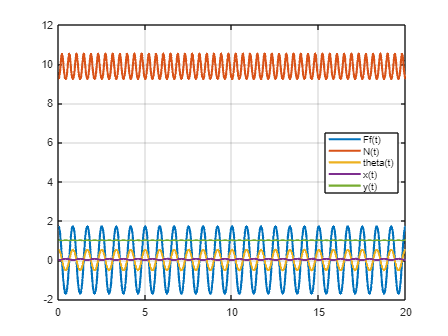

%Solve using the numerical solver.  The "unknown functions" are still x, y,
%theta, and the DE is second order in all of them.  So, you'll need to
%provide an initial condition for x and y.  Or whatever.  In any case,
%you'll need three state variables.  Essentially, you have said that we
%have to roll along the ground, but we have not said where the ground is. 

theta0 = pi/6;
omega0 = 0;
x0=0; y0=1;


soln=mechanicsAsDAE(DES,disp_const,vel_const,[0,20],{theta==theta0,diff(theta)==omega0,x==x0,y==y0});

The unknown functions (just the base functions, not derivatives) are: Ff(t),N(t),theta(t),vx(t),vy(t)
Initial Conditions:
Y0/YP0:
Ff: 1.721276 Fft:0.000000
N: 9.232456 Nt:0.000000
theta: 0.523599 thetat:0.000000
vx: 0.000000 vxt:1.721276
vy: 0.000000 vyt:-0.577544
Dthetat: 0.000000 Dthetatt:-27.216117


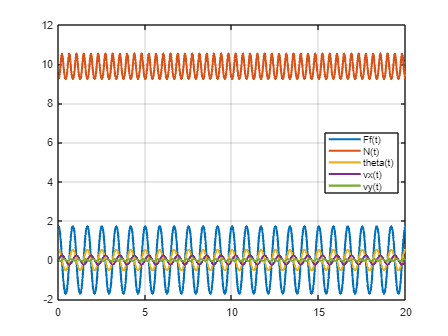

%If you notice above, the differential equation is really first order in x'
%and y'.  If you *really* don't want to solve for x and y (even though it
%is fine to just put any number you like in for x0 and y0) then you can
%formulate the problem that way. 


syms vx(t) vy(t) theta(t) Ff(t) N(t)

%Set up equations for a rolling semi-circle. Notice that the roll
%conditions are given in terms of a derivative.  This will have an impact
%in a second. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

vG=[vx(t);vy(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(vG,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vGr = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = vG == vGr(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];

soln=mechanicsAsDAE(DES,disp_const,vel_const,[0,20],{theta==theta0,diff(theta)==omega0});

%Go back to the original set up, in terms of x and y rather than vx and vy. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

rG=[x(t);y(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(rG,t,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vG = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = diff(rG,t) == vG(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];


%Once again, because you've formulated it this way, it is expected that
%you'll need four state variables.  Because the dependence is so
%simple, you can actually get away with 2.  Watch out though!  If you do this, the solver
%will say that it can set x(t) and y(t) to be anything it likes, and choose
%0!  You'll get the correct governingODEs, but there is no way to calculate
%x(t) and y(t) out of theta, so your postprocessing equations will be
%incorrect. 
[governingODEs,PPs]=analyzeSystem(DES,[],vel_const,[theta,diff(theta)]);

The unknown functions are:
Ff(force)
N(force)
theta
x
y

Expected Number of State Variables:4


%This governing ODE is correct. 
vpa(governingODEs,2)

$$ans = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{2.2e+32\,\sin\left(\theta \left(t\right)\right)\,\left(10.0\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+980.0\right)}{4.4e+33\,\cos\left(\theta \left(t\right)\right)-7.8e+33}$$

%Look at the last two entries for the post processing. It
%is just saying that x(t)=0 and y(t)=0. 
vpa(PPs,2)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=0.042\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-0.1\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\sigma_{2}\\ \frac{\partial }{\partial t}y\left(t\right)=0.042\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{0.042\,\left(2.2e+33\,\sigma_{1}\,\sigma_{3}-7.8e+33\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}+2.2e+33\,\sigma_{3}-2.2e+35\,\sigma_{1}+2.2e+35\right)}{\sigma_{4}}\\ \mathrm{Ff}\left(t\right)=\sigma_{2}\\ N\left(t\right)=\frac{2.8e-19\,\left(3.4e+50\,\sigma_{1}\,\sigma_{3}-1.2e+51\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}+3.4e+50\,\sigma_{3}-3.3e+52\,\sigma_{1}+1.6e+53\,\cos\left(\theta \left(t\right)\right)-2.4e+53\right)}{\sigma_{4}}\\ x\left(t\right)=0.0\\ y\left(t\right)=0.0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=-\frac{8.5e-3\,\left(2.5e+36\,\sin\left(\theta \left(t\right)\right)-5.4e+35\,\sigma_{5}+5.5e+33\,\sigma_{5}\,\sigma_{3}-1.3e+34\,\sin\left(\theta \left(t\right)\right)\,\sigma_{3}\right)}{\sigma_{4}}\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{4}=4.4e+33\,\cos\left(\theta \left(t\right)\right)-7.8e+33\\ \sigma_{5}=\sin\left(2.0\,\theta \left(t\right)\right) \end{array}$$

%Now you can timestep. You can solve for theta fine out of governing ODE.
%Just don't trust the results in the postprocessing equations for x and y. 
soln=timeStepODESystem(governingODEs,[0,20],[theta==theta0,diff(theta)==omega0],PPs,0);

The unknown functions (just the base functions, not derivatives) are: theta(t)


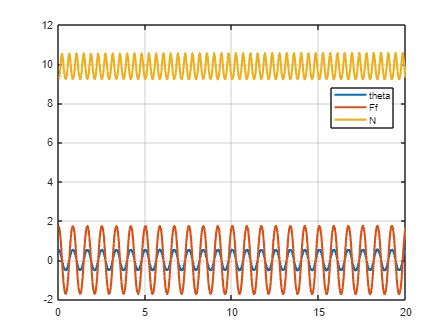

plot(soln.t,soln.theta,soln.t,soln.Ff,soln.t,soln.N,'LineWidth',2)
legend({"theta","Ff","N"},'Location','Best')
grid on

%You could have called x and y state variables, since they are in this
%formulation.  Now everything lines up, and the postprocessing equations
%can be trusted. 

[governingODEs,PPs]=analyzeSystem(DES,[],vel_const,[theta,diff(theta),x,y]);

The unknown functions are:
Ff(force)
N(force)
theta
x
y

Expected Number of State Variables:4


vpa(governingODEs,2)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{2.2e+32\,\sin\left(\theta \left(t\right)\right)\,\left(10.0\,\sigma_{1}+980.0\right)}{\sigma_{2}}\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{8.5e-3\,\left(2.5e+36\,\sin\left(\theta \left(t\right)\right)-5.4e+35\,\sigma_{4}+5.5e+33\,\sigma_{4}\,\sigma_{1}-1.3e+34\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\right)}{\sigma_{2}}\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{0.042\,\left(2.2e+33\,\sigma_{3}\,\sigma_{1}-7.8e+33\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}+2.2e+33\,\sigma_{1}-2.2e+35\,\sigma_{3}+2.2e+35\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=4.4e+33\,\cos\left(\theta \left(t\right)\right)-7.8e+33\\ \sigma_{3}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{4}=\sin\left(2.0\,\theta \left(t\right)\right) \end{array}$$

vpa(PPs,2)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=0.042\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-0.1\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right)=0.042\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \mathrm{Ff}\left(t\right)=-\frac{8.5e-3\,\left(2.5e+36\,\sin\left(\theta \left(t\right)\right)-5.4e+35\,\sigma_{4}+5.5e+33\,\sigma_{4}\,\sigma_{1}-1.3e+34\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\right)}{\sigma_{2}}\\ N\left(t\right)=\frac{2.8e-19\,\left(3.4e+50\,\sigma_{3}\,\sigma_{1}-1.2e+51\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}+3.4e+50\,\sigma_{1}-3.3e+52\,\sigma_{3}+1.6e+53\,\cos\left(\theta \left(t\right)\right)-2.4e+53\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=4.4e+33\,\cos\left(\theta \left(t\right)\right)-7.8e+33\\ \sigma_{3}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{4}=\sin\left(2.0\,\theta \left(t\right)\right) \end{array}$$

%Now you can timestep.  You'll need to give initial conditions for x,y,
%because they are state variables. 

soln=timeStepODESystem(governingODEs,[0,20],[theta==theta0,diff(theta)==omega0,x==0,y==1],PPs,0);

The unknown functions (just the base functions, not derivatives) are: theta(t),x(t),y(t)


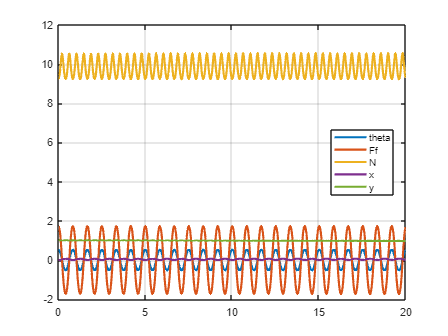

plot(soln.t,soln.theta,soln.t,soln.Ff,soln.t,soln.N,soln.t,soln.x,soln.t,soln.y,'LineWidth',2)
legend({"theta","Ff","N","x","y"},'Location','Best')
grid on

%Finally, you could formulate the whole thing in terms of vx and vy like
%above, and proceed symbolically (ish). 

syms vx(t) vy(t) theta(t) Ff(t) N(t)

%Set up equations for a rolling semi-circle. Notice that the roll
%conditions are given in terms of a derivative.  This will have an impact
%in a second. 

m = 1;      % kg
r = 0.1;    % m
g = 9.81;     % m/s^2
Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

vG=[vx(t);vy(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(vG,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vGr = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = vG == vGr(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];

[governingODEs,PPs]=analyzeSystem([DES],[],vel_const,[theta,diff(theta)])

The unknown functions are:
Ff(force)
N(force)
theta
vx
vy

Expected Number of State Variables:2


$$governingODEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{220367922943023303462492508782592\,\sin\left(\theta \left(t\right)\right)\,\left(10\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+981\right)}{4407358458860466069249850175651840\,\cos\left(\theta \left(t\right)\right)-7788445287802241602543245460631721}$$

The unknown functions (just the base functions, not derivatives) are: theta(t)


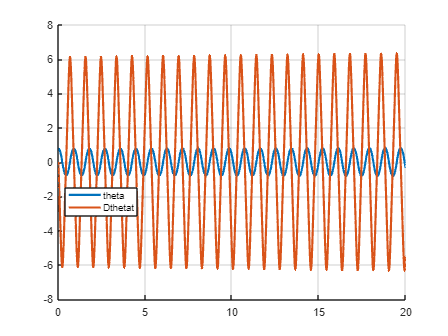

soln=timeStepODESystem(governingODEs,[0,20],[theta==pi/4,diff(theta)==0],PPs);